# Get Started with Image Classification

This example shows how to create a simple convolutional neural network for deep learning classification using the Deep Network Designer app. Convolutional neural networks are essential tools for deep learning and are especially suited for image recognition.

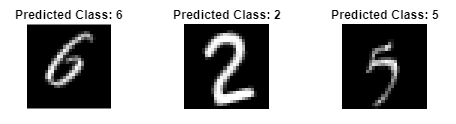

## Load Image Data

Load the digit sample data as an image datastore. To access this data, open the example as a live script. The `imageDatastore` function automatically labels the images based on folder names. The data set has 10 classes and each image in the data set is 28-by-28-by-1 pixels. 


imds = imageDatastore("DigitsData", ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames");

classNames = categories(imds.Labels);

Partition the data into training, validation, and test data sets. Use 70% of the images for training, 15% for validation, and 15% for testing. Specify `"randomized"` to assign the specified proportion of files from each class to the new data sets. The `splitEachLabel` function splits the image datastore into three new datastores.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.7,0.15,0.15,"randomized");

## Define Network Architecture

To build the network, use the Deep Network Designer app. 

deepNetworkDesigner

To create a blank network, pause on **Blank Network** and click **New**. 

In the **Designer** pane, define the convolutional neural network architecture. Drag layers from the **Layer Library** and connect them. To quickly search for layers, use the **Filter layers** search box in the **Layer Library** pane. To edit the properties of a layer, click the layer and edit the values in the **Properties** pane.

Drag these layers in order and connect them sequentially. First, drag an **imageInputLayer** onto the canvas and set **InputSize** to `28,28,1`.

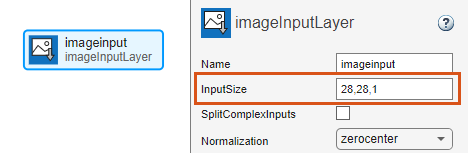

Next, drag these layers onto the canvas and connect them in order: 

- **convolution2dLayer**

- **batchNormalizationLayer**

- **reluLayer**

Then, connect a **fullyConnectedLayer** and set **OutputSize** to the number of classes in the data, in this example, 10.

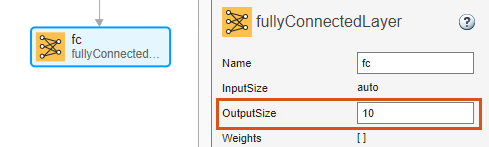

Finally, add a **softmaxLayer**.

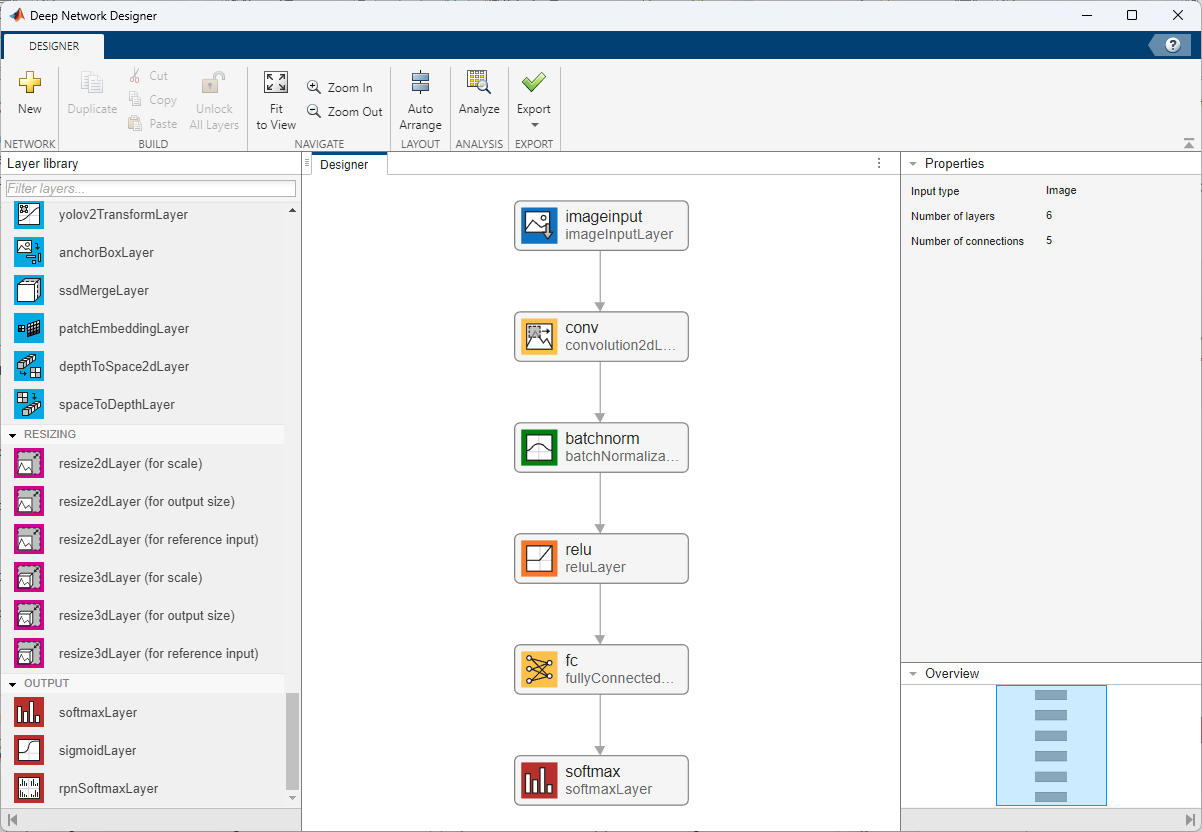

To check that the network is ready for training, click **Analyze**. The Deep Learning Network Analyzer reports zero errors or warnings, so the network is ready for training. To export the network, click **Export**. The app saves the network as the variable `net_1`.

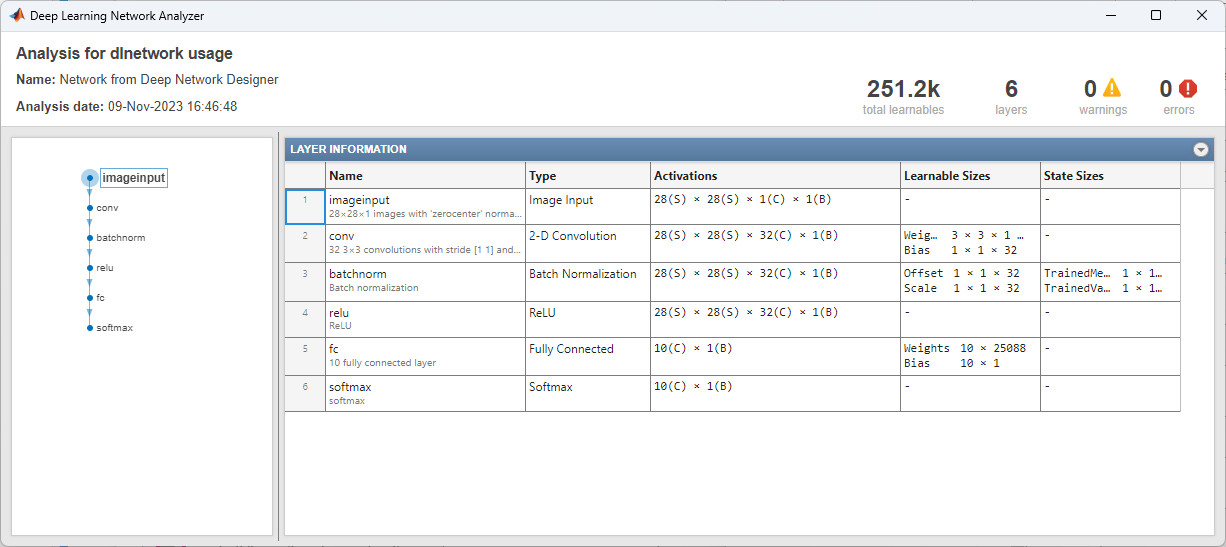

## Specify Training Options

Specify the training options. Choosing among the options requires empirical analysis. To explore different training option configurations by running experiments, you can use the [Experiment Manager](docid:nnet_ref#mw_11ce840f-eed7-4975-9c28-baeebd79f092) app. 

options = trainingOptions("sgdm", ...
    MaxEpochs=4, ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=30, ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

## **Train Neural Network**

Train the neural network using the [`trainnet`](docid:nnet_ref.mw_87a4761c-af20-4e6e-9752-e145a8295c97) function. Because the aim is classification, use cross-entropy loss.

net = trainnet(imdsTrain,net_1,"crossentropy",options);

## Test Neural Network

To test the neural network, classify the validation data and calculate the classification accuracy. 

Make predictions using the [`minibatchpredict`](docid:nnet_ref.mw_c7ae5ad7-5485-4270-8657-694ab264fb57) function and convert the scores to labels using the [`scores2label`](docid:nnet_ref.mw_b4669b80-206b-472f-a9eb-7e9642b3c38c) function. By default, the `minibatchpredict` function uses a GPU if one is available.

scores = minibatchpredict(net,imdsValidation);
YValidation = scores2label(scores,classNames);

Calculate the classification accuracy. The accuracy is the percentage of correctly predicted labels.

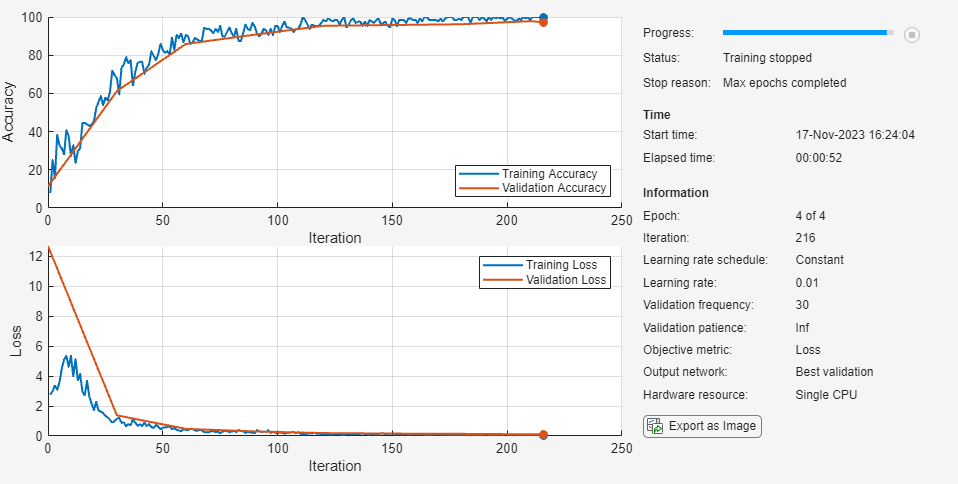

TValidation = imdsValidation.Labels;

accuracy = mean(YValidation == TValidation)

Visualize some of the predictions.

numValidationObservations = numel(imdsValidation.Files);
idx = randi(numValidationObservations,9,1);

figure
tiledlayout("flow")

accuracy = 0.9780

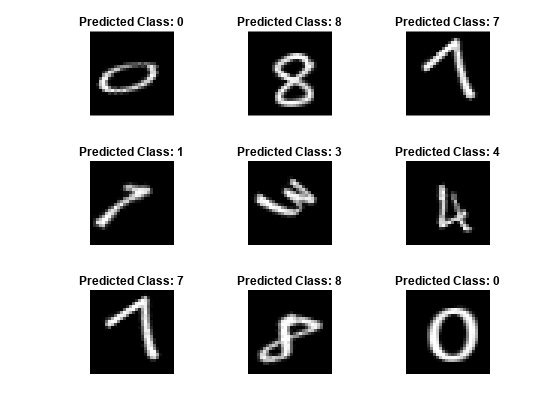

for i = 1:9
    nexttile
    img = readimage(imdsValidation,idx(i));
    imshow(img)
    title("Predicted Class: " + string(YValidation(idx(i))))
end

For next steps in deep learning, you can try using pretrained networks and transfer learning. For an example, see [Get Started with Transfer Learning](docid:nnet_gs#mw_e7f28092-4f41-4d94-9820-daffd2145d72).

*Copyright 2020-2023 The MathWorks, Inc.*